# MACM 203 Assignment 3

#### Part (a)

Load the given data file containing x and y values.

load ~/Downloads/a3.mat
x

x =    -0.8290   -0.4750    0.6020   -0.9416    0.8577    0.4607   -0.0228    0.1571   -0.5254   -0.0823    0.9262    0.0936    0.0423   -0.5368   -0.0222    0.2481    0.3583   -0.2090   -0.2651    0.9760   -0.9245    0.7703    0.8266    0.5924   -0.8026   -0.4763   -0.3293    0.3595   -0.7269    0.4425


y

y =     0.8167    0.7643    0.7345    0.8485    0.7607    0.7308    0.7303    0.7202    0.7713    0.7260    0.7627    0.7253    0.7241    0.7706    0.7304    0.7228    0.7245    0.7404    0.7442    0.7753    0.8385    0.7462    0.7588    0.7292    0.8151    0.7596    0.7517    0.7255    0.8009    0.7257


Ensure x and y are column vectors for correct matrix operations.

x = x';
y = y';

Transform the given nonlinear equation into a linear system.

We rewrite the equation as: -x*a + cos(x)*y^2*b + y^2*c = 1.

Construct matrix A using x, cos(x), and y values.

Right-hand side is a vector of ones.

A = [-x, cos(x).*y.^2, y.^2];
B = ones(size(y));

Solve the overdetermined system using the least-squares method.

X = A\B

X =    -0.0999
    0.8709
    1.0214


#### Part (b)

Extract the computed values of a, b, and c from the solution vector.

a = X(1)

a = -0.0999

b = X(2)

b = 0.8709

c = X(3)

c = 1.0214

#### Part (c)

Generate a smooth set of x values for plotting the fitted curve.

x_smooth = linspace(min(x), max(x));

Compute the corresponding y values using the obtained a, b, and c.

y_smooth = sqrt((a*x_smooth+1)./(b*cos(x_smooth)+c));

Plot the original data points as circles and the fitted curve.

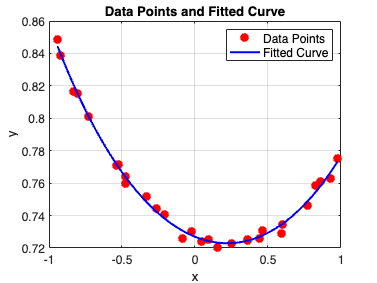

figure;
plot(x, y, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
hold on;
plot(x_smooth, y_smooth, 'b-', 'LineWidth', 2);
hold off;
grid on;
xlabel('x', 'FontSize', 12);
ylabel('y', 'FontSize', 12);
title('Data Points and Fitted Curve', 'FontSize', 14);
legend('Data Points', 'Fitted Curve', 'FontSize', 12);
set(gca, 'FontSize', 12);

#### Part (d)

Define an anonymous function to generate the m×n matrix where each entry at (i,j) is computed as 2*i + j.

f = @(m,n) 2*(1:m)'+(1:n);

#### Part (e)

Call the function to generate the required 2×3 matrix.

f(2,3)

ans =      3     4     5
     5     6     7
